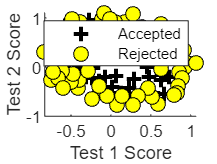

% 加载数据
data = load("D:\tree\Machine Learning\CS229-code\ex2data2.txt");
X = data(:, [1, 2]); % 特征
y = data(:, 3); % 标签

% 可视化数据
figure; hold on;
pos = find(y == 1);
neg = find(y == 0);
plot(X(pos, 1), X(pos, 2), 'k+','LineWidth', 2, 'MarkerSize', 7);
plot(X(neg, 1), X(neg, 2), 'ko', 'MarkerFaceColor', 'y', 'MarkerSize', 7);
xlabel('Test 1 Score');
ylabel('Test 2 Score');
legend('Accepted', 'Rejected');
hold off;


% 特征映射
degree = 6;
X_poly = mapFeature(X(:,1), X(:,2));

% 拟合模型
mdl = fitclinear(X_poly, y, 'Learner', 'logistic', 'Regularization', 'ridge', 'Lambda', 1);

% 打印最终代价
theta = mdl.Beta;
fprintf('Final cost: %f\n', costFunctionReg(theta, X_poly, y, 1));

Final cost: 0.682221


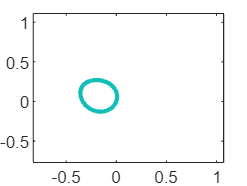


% 决策边界绘制
plotDecisionBoundary(theta, X_poly, y);


% 特征映射函数

function out = mapFeature(X1, X2)
    degree = 6;
    out = ones(size(X1));
    for i = 1:degree
        for j = 0:i
            out(:, end+1) = (X1.^(i-j)).*(X2.^j);
        end
    end
end

% 成本函数计算
function J = costFunctionReg(theta, X, y, lambda)
    m = length(y);
    h = sigmoid(X * theta);
    J = (1/m) * (-y' * log(h) - (1 - y)' * log(1 - h)) + (lambda / (2*m)) * sum(theta(2:end).^2);
end

% Sigmoid函数
function g = sigmoid(z)
    g = 1.0 ./ (1.0 + exp(-z));
end

% 决策边界绘制
function plotDecisionBoundary(theta, X, y)
    figure; hold on;
    % 绘制数据点
    plotData(X(:,2:3), y);
    
    % 计算决策边界
    if size(X, 2) <= 3
        % 只需要两个特征时，直接绘制线
        plot_x = [min(X(:,2))-2, max(X(:,2))+2];
        plot_y = (-1./theta(3)).*(theta(2).*plot_x + theta(1));
        plot(plot_x, plot_y, 'b-', 'LineWidth', 2);
        legend('y = 1', 'y = 0', 'Decision Boundary');
        axis([30, 100, 30, 100]);
    else
        % 多特征时，绘制等高线
        u = linspace(min(X(:,2)), max(X(:,2)), 50);
        v = linspace(min(X(:,3)), max(X(:,3)), 50);
        [U, V] = meshgrid(u, v);
        Z = mapFeature(U(:), V(:)) * theta;
        Z = reshape(Z, size(U));
        contour(U, V, Z, [0, 0], 'LineWidth', 2);
    end
    hold off;
end

% 绘制数据点函数
function plotData(X, y)
    % 找到正负类的索引
    pos = find(y == 1);
    neg = find(y == 0);

    % 绘制正类数据点
    plot(X(pos, 1), X(pos, 2), 'k+','LineWidth', 2, 'MarkerSize', 7);
    hold on;

    % 绘制负类数据点
    plot(X(neg, 1), X(neg, 2), 'ko', 'MarkerFaceColor', 'y', 'MarkerSize', 7);

    hold off;
end
